# Interactive MATLAB Lab 1.7: Explicit and Implicit Solution Explorer

In a Live Script, turn c into a slider.

c = 5;

syms xs ys
implicitFunction = xs^2 + ys^2 - c;
implicitDerivative = simplify( ...
    -diff(implicitFunction,xs)/diff(implicitFunction,ys) );

radius = sqrt(c);

disp("Implicit relation: x^2 + y^2 = " + string(c))

Implicit relation: x^2 + y^2 = 5


disp("Explicit branches: y = +/-sqrt(c-x^2)")

Explicit branches: y = +/-sqrt(c-x^2)


disp("Implicit derivative dy/dx:")

Implicit derivative dy/dx:


disp(implicitDerivative)

$$-\frac{\mathrm{xs}}{\mathrm{ys}}$$

disp("Real domain: -sqrt(c) <= x <= sqrt(c)")

Real domain: -sqrt(c) <= x <= sqrt(c)


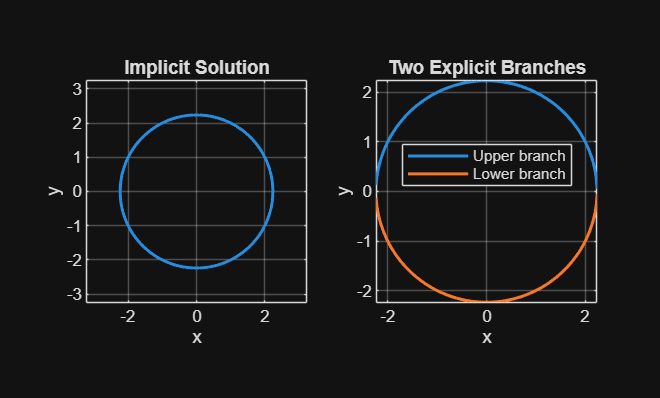


figure
subplot(1,2,1)
fimplicit(@(x,y) x.^2 + y.^2 - c, ...
    [-radius-1 radius+1 -radius-1 radius+1], ...
    'LineWidth',1.5)
axis equal
grid on
xlabel('x')
ylabel('y')
title('Implicit Solution')

subplot(1,2,2)
fplot(@(x) sqrt(c-x.^2),[-radius radius],'LineWidth',1.5)
hold on
fplot(@(x) -sqrt(c-x.^2),[-radius radius],'LineWidth',1.5)
hold off
axis equal
grid on
xlabel('x')
ylabel('y')
title('Two Explicit Branches')
legend('Upper branch','Lower branch','Location','best')